# Isothermal Batch Reactor 

In this case, a batch reactor will be studied which involves consecutive and parallel reactions. General Material Balance is written as:


$$\frac{d\left(c_i V\right)}{\mathrm{dt}}=\sum_{j=1}^R \nu {\;}_{i,j} R_j V$$


The reaction network is:

$A\leftrightarrow B\to C$  with $k_1 \;\mathrm{and}\;k_{-1}$ are kinetics constant for conversion A to B, and k2 is kinetics constant for conversion B to C

$2A\to D$ with k3 is kinetics constant for conversion C to D

the reaction kinetics equations for **A** and **B** are written as follows:


$$\begin{array}{l}
\frac{{\mathrm{dC}}_A }{\mathrm{dt}}=-k_1 C_A +k_{-1} C_B -2k_3 C_A^2 \\
\frac{{\mathrm{dC}}_B }{\mathrm{dt}}=k_1 C_A -\left(k_{-1} +k_2 \right)C_B 
\end{array}$$


clear,clc
CA0 = 1;        % Initial Concentration of A [mol/cm3/s]
CB0 = 0;        % Initial Concentration of B [mol/cm3/s]
CC0 = 0;        % Initial Concentration of C [mol/cm3/s]
CD0 = 0;        % Initial Concentration of D [mol/cm3/s]
y0 = [CA0; CB0; CC0; CD0];
tspan = 0:0.1:30;       % Time Domain
[t,y] = ode23s(@batch,tspan,y0);
CA = y(:,1);
CB = y(:,2);
CC = y(:,3);
CD = y(:,4);

## Graphics

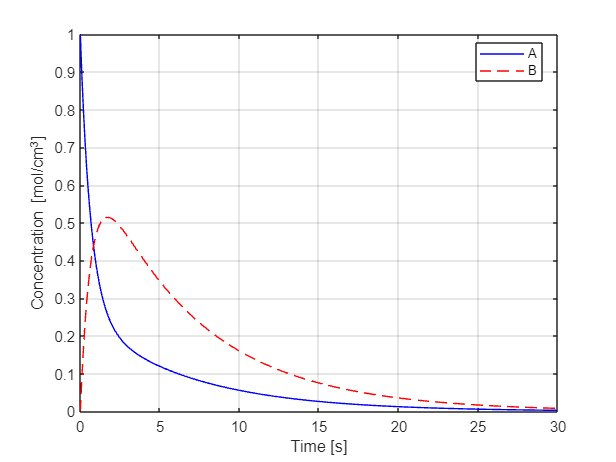

plot(t,CA,'Color','b'); hold on; plot(t,CB,'--','Color','r')
xlabel('Time [s]'); ylabel('Concentration [mol/cm^{3}]')
grid on; legend('A','B','Location','best'); hold off

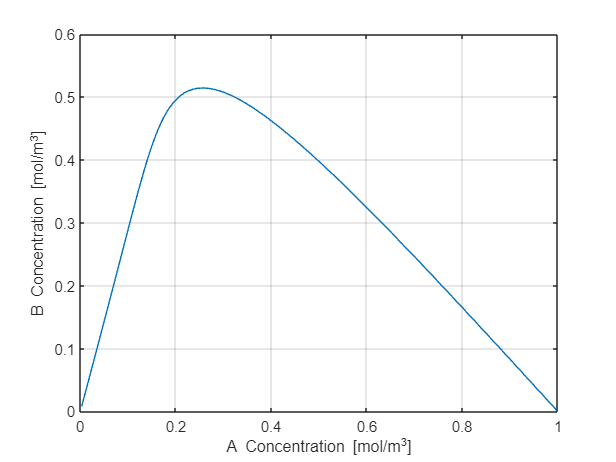

plot(CA,CB); xlabel('A Concentration [mol/m^{3}]'); ylabel('B Concentration [mol/m^{3}]'); grid on

Conversion_A = 1 - CA(end)/CA(1);
Selectivity_A_C = -(CC(end)-CC(1))/(CA(end)-CA(1));
Yield_A_C = Conversion_A*Selectivity_A_C;
table(Conversion_A,Selectivity_A_C,Yield_A_C)

ans = 1×3 table
    Conversion_A    Selectivity_A_C    Yield_A_C
    ____________    _______________    _________

      0.99717           0.86579         0.86334 


function dydt = batch(t,y)
    k1 = 1;
    k_1 = 0.3;
    k2 = 0.2;
    k3 = 0.1;
    
    dCA = -k1*y(1) + k_1*y(2) - 2*k3*y(1)^2;
    dCB = k1*y(1) - (k_1 + k2)*y(2);
    dCC = k2*y(2);
    dCD = k3*y(1)^2;
    
    dydt = [dCA; dCB; dCC; dCD];
end